# Autocorrelation in timeseries

Code from [https://github.com/WeitzGroup/analyzing_microbiome_timeseries](https://github.com/WeitzGroup/analyzing_microbiome_timeseries) 

% add helper_function directory to matlab path
addpath('helper_functions');

First, generate independent random walks:


$$X_t =X_{t-1} +\varepsilon_t$$


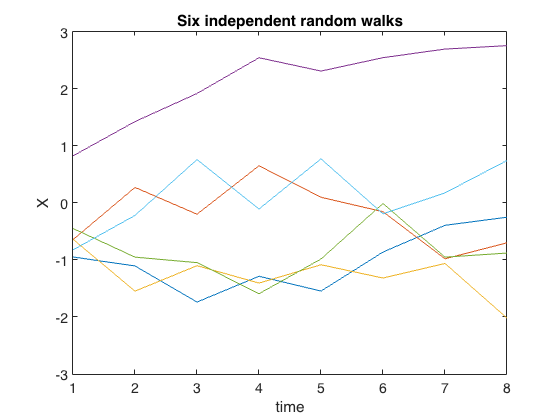

clear;

N = 6; % number of timeseries
NT = 8; % number of timepoints
epsilon = 2*rand(NT,N)-1; % random numbers between -1 and +1

phi = +1;
if abs(phi)>1; fprintf('WARNING: timeseries will be divergent!\n'); end

% generate random walks
X = zeros(NT,N);
X(1,:) = epsilon(1,:);
for i = 2:NT
    X(i,:) = phi*X(i-1,:) + epsilon(i,:);
end
clear i;

figure();
plot(X);
xlabel('time');
ylabel('X');
title('Six independent random walks');
set(gca,'FontSize',14);

Some of the random walks appear highly correlated (and anticorrelated), despite being independent. Significant correlations (p<0.05) are marked with black stars.

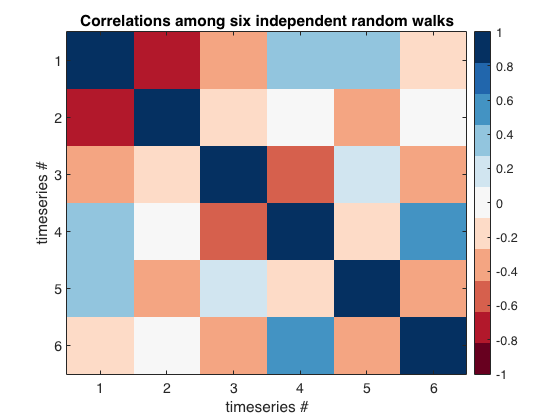

[rho_X, pval_X] = corr(X);

figure();
plot_correlation(rho_X,pval_X);
title('Correlations among six independent random walks');

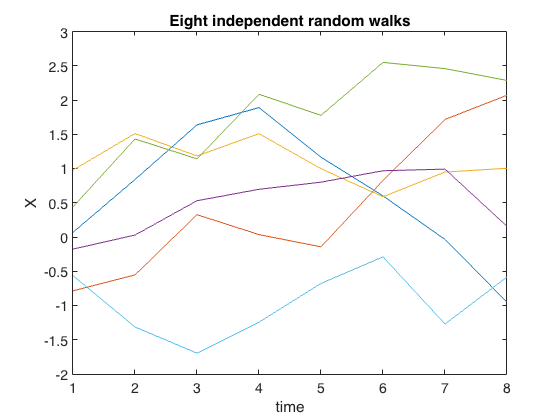


N = 6; % number of timeseries
NT = 8; % number of timepoints
epsilon = 2*rand(NT,N)-1; % random numbers between -1 and +1

phi = +1;
if abs(phi)>1; fprintf('WARNING: timeseries will be divergent!\n'); end

% generate random walks
X = zeros(NT,N);
X(1,:) = epsilon(1,:);
for i = 2:NT
    X(i,:) = phi*X(i-1,:) + epsilon(i,:);
end
clear i;

figure();
plot(X);
xlabel('time');
ylabel('X');
title('Eight independent random walks');
set(gca,'FontSize',14);

Some of the random walks appear highly correlated (and anticorrelated), despite being independent. Significant correlations (p<0.05) are marked with black stars.

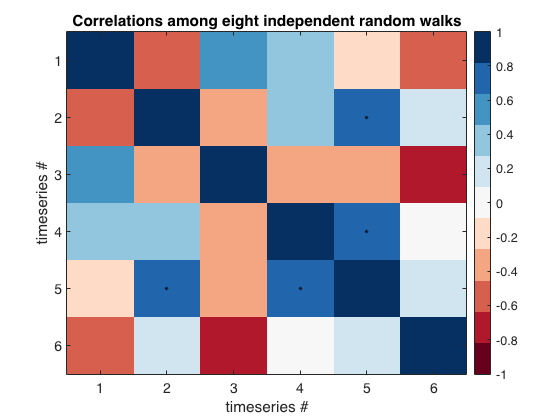

[rho_X, pval_X] = corr(X);

figure();
plot_correlation(rho_X,pval_X);
title('Correlations among eight independent random walks');